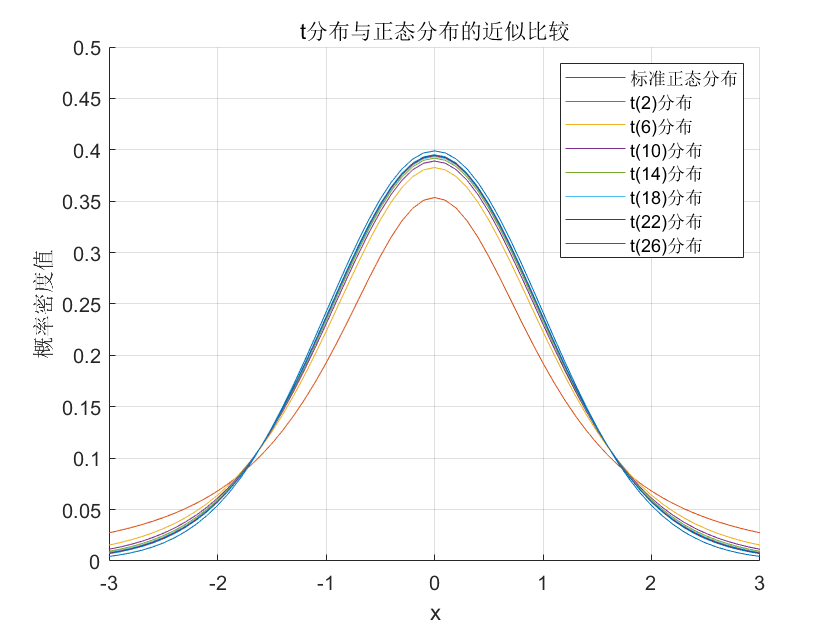

% 实验6 t分布与正态分布的近似关系

xs = -3:0.1:3;
tys = zeros(7, 61);
norm_ys = normpdf(xs, 0, 1);

for i = 1:7
    tys(i, :) = tpdf(xs, 2 + 4 * (i - 1));
end

hold on; axis on; grid on;
str_mats = strings(8);
plot(xs, norm_ys);
str_mats(1) = "标准正态分布";
for i = 1:7
    plot(xs, tys(i, :));
    str_mats(i + 1) = sprintf("t(%d)分布", 2 + 4 * (i - 1));
end
xlim([-3, 3]);
ylim([0, 0.5]);
legend(str_mats(1:8));
xlabel("x");
ylabel("概率密度值");
title("t分布与正态分布的近似比较");